# Obtaining $X(\Omega)$ from $X[k]$

This live script is based on the discussion in MATLAB Exercise 7.4 of 

*Discrete-Time Signals and Systems: A MATLAB Integrated Approach*

by O. Alkin, CRC Press, 2025.

The DFT $X[k]$ of a length $N$ signal is provided. How can we obtain the DTFT of the signal without resorting to finding $x[n]$ by means of an inverse DFT? Recall that

$  X\left(\Omega\right) = 
  \sum_{k=0}^{N-1} X[k]\,B_{N}\left(\Omega-\frac{2\pi k}{N}\right)$                    (7.16)

where the interpolating function is

$  B_{N}\left(\Omega\right) = 
  \frac{\sin\left(\frac{\Omega N}{2}\right)}
  {N\,\sin\left(\frac{\Omega}{2}\right)}\,e^{-j\Omega\left(N-1\right)/2}$                    (7.15)

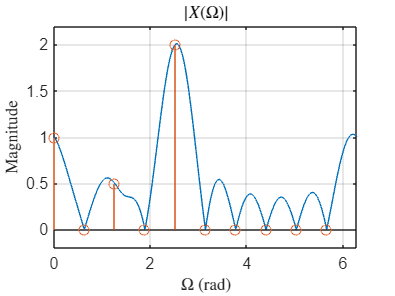

% Variable 'Xk' holds the vector of DFT samples. Feel free to modify it.
Xk = [1,0,0.5,0,2,0,0,0,0,0];

N = length(Xk);
Omg = ([0:1023]/1024+eps)*2*pi;   % Vector of angular frequencies
XDTFT = zeros(size(Omg));
% Compute DTFT using Eqn. (7.16)
for k=0:N-1
  XDTFT = XDTFT + Xk(k+1)*B(Omg-2*pi*k/N,N);
end
k = [0:N-1];
% Graph magnitude and phase
plot(Omg,abs(XDTFT)); grid;
axis([0,2*pi,-0.2,2.2]);
set(0,'defaultTextInterpreter','latex');
xlabel('$\Omega$ (rad)');
ylabel('Magnitude');
title('$|X(\Omega)|$');
hold on;
stem(2*pi*k/N,abs(Xk(k+1)),'o');
hold off;

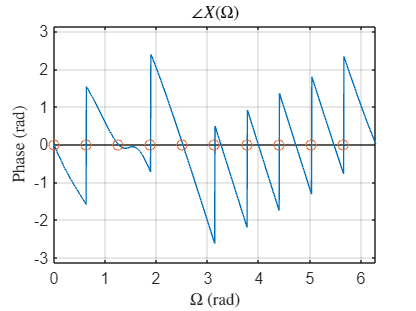

plot(Omg,angle(XDTFT)); grid;
axis([0,2*pi,-pi,pi]);
xlabel('$\Omega$ (rad)');
ylabel('Phase (rad)');
title('$\angle X(\Omega)$')
hold on;
stem(2*pi*k/N,angle(Xk(k+1)),'o');
hold off;

set(0,'defaultTextInterpreter','tex');

function out = B(Omg,N)
% Local function to evaluate the BN(Omega) given by Eqn. (7.15)
  mag = sin(N*Omg/2)./(N*sin(Omg/2));
  phs = -Omg*(N-1)/2;
  out = mag.*exp(j*phs);
end